clc;
clear;
close all;

%% PARAMETERS
N = 1e4;                  % Number of bits
Rb = 1e9;                 % Bit rate (1 Gbps)
Fs = 10e9;                % Sampling frequency (10 GHz)
samples_per_bit = Fs/Rb;

num_channels = 4;

% SAFE carrier frequencies (within Nyquist)
fc = [1e9 2e9 3e9 4e9];   

t = (0:N*samples_per_bit-1)/Fs;

%% TRANSMITTER

data = randi([0 1], num_channels, N);
tx_signal = zeros(num_channels, length(t));

for i = 1:num_channels
    
    % OOK modulation
    bits = repelem(data(i,:), samples_per_bit);
    
    % Carrier modulation
    carrier = cos(2*pi*fc(i)*t);
    
    tx_signal(i,:) = bits .* carrier;
end

% WDM Multiplexing
wdm_signal = sum(tx_signal, 1);

%% CHANNEL

% Fiber attenuation
L = 20;             % km
alpha = 0.2;        % dB/km
attenuation = 10^(-alpha*L/10);

rx_signal = wdm_signal * attenuation;

% Add AWGN noise
SNR_dB = 20;
rx_signal = awgn(rx_signal, SNR_dB, 'measured');

%% RECEIVER (DEMULTIPLEXING)

rx_bits = zeros(num_channels, N);

for i = 1:num_channels
    
    % Bandpass FIR Filter (normalized frequency)
    bw = 0.2e9; % bandwidth
    
    Wn = [(fc(i)-bw)/(Fs/2) (fc(i)+bw)/(Fs/2)];
    b = fir1(100, Wn); 
    
    filtered_signal = filter(b, 1, rx_signal);
    
    % Coherent detection
    carrier = cos(2*pi*fc(i)*t);
    baseband = filtered_signal .* carrier;
    
    % Low-pass filter
    Wn_lpf = (Rb)/(Fs/2);
    b_lpf = fir1(100, Wn_lpf);
    
    detected = filter(b_lpf, 1, baseband);
    
    % Sampling
    samples = detected(samples_per_bit:samples_per_bit:end);
    
    % Threshold detection
    threshold = mean(samples);
    rx_bits(i,:) = samples > threshold;
end

%% BER CALCULATION

BER = zeros(1, num_channels);

for i = 1:num_channels
    [~, BER(i)] = biterr(data(i,:), rx_bits(i,:));
    fprintf('Channel %d BER = %e\n', i, BER(i));
end

Channel 1 BER = 4.921000e-01
Channel 2 BER = 4.983000e-01
Channel 3 BER = 4.956000e-01
Channel 4 BER = 5.088000e-01


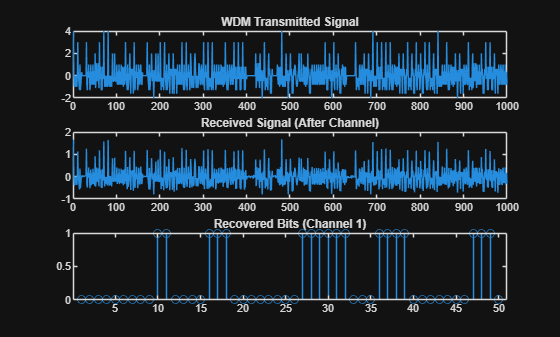


%% PLOTS

figure;

subplot(3,1,1);
plot(wdm_signal(1:1000));
title('WDM Transmitted Signal');

subplot(3,1,2);
plot(rx_signal(1:1000));
title('Received Signal (After Channel)');

subplot(3,1,3);
stem(rx_bits(1,1:50));
title('Recovered Bits (Channel 1)');